addpath('API_MO');
addpath('src');
SOFAstart;
addpath('HRTFs/SADIE/D1_HRIR_SOFA')
hrtf = SOFAload('D1_44K_16bit_256tap_FIR_SOFA.sofa');

%   ITD -> output variable (s)
%
%   hrtf -> SOFA file
%   azmth -> azimuth angle
%   elev -> elevation angle

%% Buscamos la posición del ángulo dado:
pos = find(hrtf.SourcePosition(:,2) == 0 &  hrtf.SourcePosition(:,1) == 0); %elev y azimuth
fs = hrtf.Data.SamplingRate;
OS = 10;

A = reshape(hrtf.Data.IR(pos,1,:), [1, length(hrtf.Data.IR(pos,1,:))]); %%convertimos los datos en 1x512
B = reshape(hrtf.Data.IR(pos,2,:), [1, length(hrtf.Data.IR(pos,2,:))]); 

%% Oversampling
ta = 0:1/fs:(length(A)-1)/fs;
ty = 0:1/(OS*fs):(length(A)-1)/(fs);
Y = interp1(ta,A,ty); %% Oversampling x10
Z = interp1(ta,B,ty);

%% LPF
if strcmp(hrtf.GLOBAL_DatabaseName, 'ARI')
    fc = 2000;
elseif strcmp(hrtf.GLOBAL_DatabaseName, 'CIPIC')
    fc = 3000;
elseif strcmp(hrtf.GLOBAL_DatabaseName, 'LISTEN')
    fc = 500;
else
    fc = 5000;
end

FIR = designfilt('lowpassfir', 'FilterOrder', 128, 'CutoffFrequency', fc, 'SampleRate', fs*OS); % Generación de coeficientes FIR
FL = filter(FIR, Y)

FL =    0.000123141247691   0.000198143524087   0.000225629472923   0.000205713651124   0.000137977476801   0.000021465933295  -0.000145292716565  -0.000364243253461  -0.000637735230892  -0.000968429817623  -0.001359181809899  -0.001812897227593  -0.002332367269182  -0.002920079759927  -0.003578009581018  -0.004307389910308  -0.005108466432962  -0.005980236988381  -0.006920179404098  -0.007923970523694  -0.008985199660703  -0.010082765775629  -0.011205106696331  -0.012337607611543  -0.013462335786304  -0.014557793633024  -0.015598694007433  -0.016555761451259  -0.017395562907922  -0.018080371195555  -0.018568064235343  -0.018725863832029  -0.018501929534933  -0.017839214293091  -0.016675585737422  -0.014944032587301  -0.012572957493612  -0.009486556569493  -0.005605284772912  -0.000846405205028   0.004875380711724   0.011634912173278   0.019520306978785   0.028619808304290   0.039020890623403   0.050809321191493   0.064068186086056   0.078876890445621   0.095310143097736   0.1134369362

FR = filter(FIR, Z)

FR =                    0  -0.000024628249538  -0.000074108254171  -0.000148877450424  -0.000249571160818  -0.000376995120505  -0.000532086355367  -0.000715862354200  -0.000929358645188  -0.001173555057085  -0.001449291116395  -0.001818741824818  -0.002282730871270  -0.002842164502403  -0.003497871176942  -0.004250406469915  -0.005099824042467  -0.006045414014579  -0.007085410596004  -0.008216671338140  -0.009434330859846  -0.010657547618079  -0.011876215956983  -0.013076708856749  -0.014241515061459  -0.015348905536111  -0.016372634996769  -0.017281683971912  -0.018040046492891  -0.018606568080430  -0.018934838196509  -0.018948512522455  -0.018590357551796  -0.017797706919240  -0.016502617482741  -0.014632102758185  -0.012108444055667  -0.008849578725582  -0.004769563970608   0.000220886272287   0.006213794816017   0.013364820050655   0.021769941617650   0.031526221281417   0.042730929878637   0.055480606138460   0.069870055024469   0.085991294208384   0.103932458164174   0.1237766701

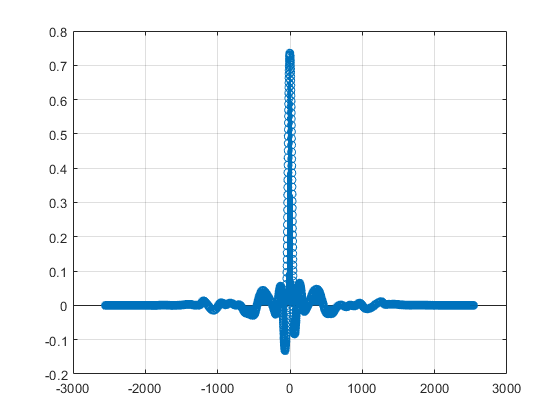


% figure(); 
% subplot(1, 2, 1); plot(ty, Y, ty, FL, 'red'); grid on;
% xlabel('Time (s)');
% ylabel('Amplitude');
% title(['Left']);
% 
% subplot(1, 2, 2); plot(ty, Z, ty, FR, 'red'); grid on;
% xlabel('Time (s)');
% ylabel('Amplitude');
% title(['Right']);

%% Cross-Correlation function
[C, T] = xcorr(FL,FR);
 figure(); 
 stem(T,C);
 grid on;

C

C =   -0.201898288624759  -0.292404418008272   0.128797184122691   0.073101104502068  -0.142721204027847   0.062658089573201   0.052215074644334  -0.055696079620623  -0.027848039810312  -0.334176477723739  -0.208860298577337   0.243670348340226  -0.153164218956714  -0.027848039810312  -0.104430149288668   0.139240199051558  -0.153164218956714                   0  -0.334176477723739  -0.264556378197960   0.194936278672181   0.020886029857734   0.006962009952578   0.097468139336091   0.348100497628895  -0.055696079620623   0.034810049762889   0.208860298577337   0.174050248814447   0.271518388150538   0.160126228909292  -0.125316179146402   0.055696079620623   0.257594368245382   0.083544119430935   0.062658089573201  -0.313290447866005  -0.041772059715467   0.013924019905156   0.139240199051558   0.257594368245382   0.107911154264957   0.229746328435071   0.142721204027847  -0.090506129383513  -0.229746328435071   0.163607233885581  -0.052215074644334   0.125316179146402   0.40727758222

T

T =        -2550       -2549       -2548       -2547       -2546       -2545       -2544       -2543       -2542       -2541       -2540       -2539       -2538       -2537       -2536       -2535       -2534       -2533       -2532       -2531       -2530       -2529       -2528       -2527       -2526       -2525       -2524       -2523       -2522       -2521       -2520       -2519       -2518       -2517       -2516       -2515       -2514       -2513       -2512       -2511       -2510       -2509       -2508       -2507       -2506       -2505       -2504       -2503       -2502       -2501


%%ITD será el valor del eje de abscisa donde se encuentre el valor máximo
%%de los valores obtenidos por la Correlación Cruzada
Tmax = find(C == max(C),1) - (length(C)+1)/2;
ITD = Tmax/(fs*OS)

ITD =     -4.535147392290249e-06
